Data file name

clear; clc;
dataFileName = 'tial_8.txt';
if ~isfile(dataFileName)
    error('File %s not found in the current directory.', dataFileName);
end
fileID = fopen(dataFileName, 'r');
% Skip the first 5 lines (header information)
for i = 1:5
    fgetl(fileID);
end
% Read the data columns
% Format: Time(s) | V_P2(V) | V_Q(V) | P2(MPa) | Q(L/min) | Safety
data = textscan(fileID, '%f %f %f %f %f %s');
fclose(fileID);
% Extract the variables globally for plotting
time_s  = data{1};
V_P2    = data{2};
V_Q     = data{3};
P2_MPa  = data{4};
Q_L_min = data{5};
if isempty(time_s)
    error('No data found in %s.', dataFileName);
end
disp('Data successfully extracted and ready for plotting.');

Data successfully extracted and ready for plotting.


plot saved data

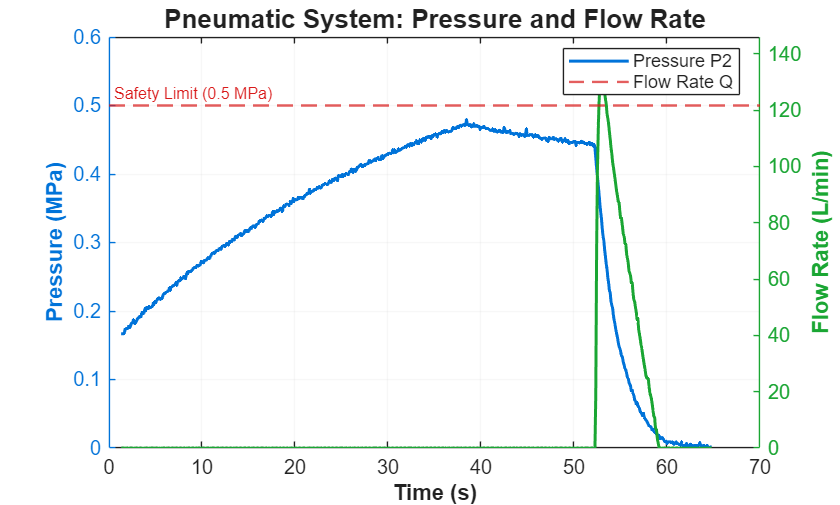

% 4. Create the dual-axis plot
figure('Name', 'Saved Pneumatic Data', 'NumberTitle', 'off', 'Color', 'white');

% Enable left y-axis for Pressure
yyaxis left;
plot(time_s, P2_MPa, '-', 'Color', [0.0 0.45 0.85], 'LineWidth', 1.5);
ylabel('Pressure (MPa)', 'FontWeight', 'bold');
% Set left y-axis limits to start at 0, and add a little padding on top
ylim([0, max([0.6, max(P2_MPa) * 1.1])]);
% Add safety limit line
yline(0.5, '--', 'Color', [0.85 0.1 0.1], 'LineWidth', 1.2, 'Label', 'Safety Limit (0.5 MPa)', 'LabelHorizontalAlignment', 'left', 'FontSize', 8);
set(gca, 'YColor', [0.0 0.45 0.85]); % Match axis color to line color

% Enable right y-axis for Flow Rate
yyaxis right;
plot(time_s, Q_L_min, '-', 'Color', [0.1 0.65 0.2], 'LineWidth', 1.5);
ylabel('Flow Rate (L/min)', 'FontWeight', 'bold');
% Set right y-axis limits to start at 0
ylim([0, max([10, max(Q_L_min) * 1.1])]);
set(gca, 'YColor', [0.1 0.65 0.2]); % Match axis color to line color

% X-axis and general plot settings
xlabel('Time (s)', 'FontWeight', 'bold');
title('Pneumatic System: Pressure and Flow Rate', 'FontSize', 13, 'FontWeight', 'bold');
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8]);

% Add a legend
legend({'Pressure P2', 'Flow Rate Q'}, 'Location', 'best');

see all datasets in one experiment

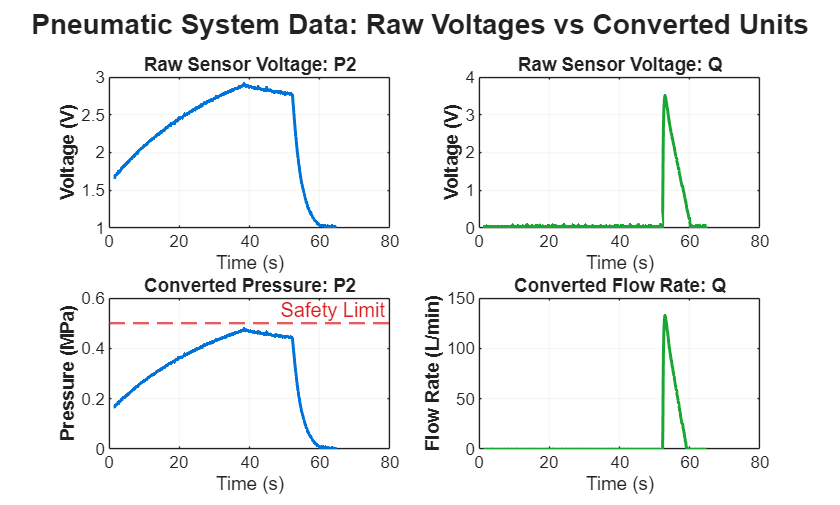


% 4. Create a figure with 4 subplots
figure('Name', 'Saved Pneumatic Data - 4 Subplots', 'NumberTitle', 'off', 'Color', 'white');

% --- Subplot 1: V_P2 (Voltage) ---
subplot(2, 2, 1);
plot(time_s, V_P2, '-', 'Color', [0.0 0.45 0.85], 'LineWidth', 1.5);
ylabel('Voltage (V)', 'FontWeight', 'bold');
xlabel('Time (s)');
title('Raw Sensor Voltage: P2');
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8]);

% --- Subplot 2: V_Q (Voltage) ---
subplot(2, 2, 2);
plot(time_s, V_Q, '-', 'Color', [0.1 0.65 0.2], 'LineWidth', 1.5);
ylabel('Voltage (V)', 'FontWeight', 'bold');
xlabel('Time (s)');
title('Raw Sensor Voltage: Q');
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8]);

% --- Subplot 3: P2 (Pressure) ---
subplot(2, 2, 3);
plot(time_s, P2_MPa, '-', 'Color', [0.0 0.45 0.85], 'LineWidth', 1.5);
hold on;
yline(0.5, '--', 'Color', [0.85 0.1 0.1], 'LineWidth', 1.2, 'Label', 'Safety Limit');
hold off;
ylabel('Pressure (MPa)', 'FontWeight', 'bold');
xlabel('Time (s)');
title('Converted Pressure: P2');
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8]);
ylim([0, max([0.6, max(P2_MPa) * 1.1])]);

% --- Subplot 4: Q (Flow Rate) ---
subplot(2, 2, 4);
plot(time_s, Q_L_min, '-', 'Color', [0.1 0.65 0.2], 'LineWidth', 1.5);
ylabel('Flow Rate (L/min)', 'FontWeight', 'bold');
xlabel('Time (s)');
title('Converted Flow Rate: Q');
grid on;
set(gca, 'GridColor', [0.8 0.8 0.8]);

% Overall Title
sgtitle('Pneumatic System Data: Raw Voltages vs Converted Units', 'FontSize', 14, 'FontWeight', 'bold');